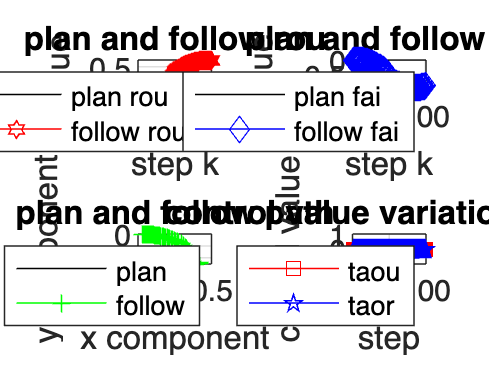

clear all
close all
clc

%planning path
% shape I
t=1:100;
rou0=0+t*1;
fai0=pi/4+t*0;

% shape O
% t=-0.49*pi:0.01*pi:0.5*pi;
% rou0=2*10*cos(t);
% fai0=t;

% shape S
% t=0.01:0.02*pi:2*pi;
% rou0=sqrt(t.*t+sin(t).*sin(t));
% fai0=atan(sin(t)./t);

% % shape 8
% a=2;
% t=0.01:0.02*pi:2*pi;
% x=-a+a.*cos(t)./(1+sin(t).^2);
% y=a.*sin(t).*cos(t)./(1+sin(t).^2);
% rou0=sqrt(x.^2+y.^2);
% fai0=atan(y./x);

% % shape SmartLake
% SmartLake=csvread('TJlake.csv');
% rou0=0.05*(sqrt(SmartLake(:,1).^2+SmartLake(:,2).^2))';
% fai0=(atan(SmartLake(:,2)./SmartLake(:,1)))';

TJ=[fai0;rou0].*0;
LTJ=length(TJ);
%planning path

% normal distribution of wind current and wave
zt0=normrnd(1.00,0.44,1,LTJ);
cr0=normrnd(0.25,0.11,1,LTJ);
wd0=normrnd(7.80,2.53,1,LTJ);

% new distribution of wind current and wave
wd1=sort(wd0);
b1=size(wd1,2);
wd11=[];
wd12=[];
for i=1:2:b1
    wd11=[wd11,wd1(i)];
    wd12=[wd12,wd1(i+1)];
end
wd122=sort(wd12,'descend');
wd=[wd11,wd122];
wd_dot=[];
for j=1:b1-1
    wd_dot=[wd_dot,(wd(j+1)-wd(j))/0.01];
end
% wd_dot=[wd(1)/0.01,wd_dot];
% wind speed normal distribution
% current speed normal (chi-square) distribution
cr1=sort(cr0);
b2=size(cr1,2);
cr11=[];
cr12=[];
for i=1:2:b2
    cr11=[cr11,cr1(i)];
    cr12=[cr12,cr1(i+1)];
end
cr122=sort(cr12,'descend');
cr=[cr11,cr122];
cr_dot=[];
for j=1:b2-1
    cr_dot=[cr_dot,(cr(j+1)-cr(j))/0.01];
end
% cr_dot=[cr(1)/0.01,cr_dot];
% current speed normal (chi-square) distribution
% wave parameter normal distribution
zt1=sort(zt0);
b3=size(zt1,2);
zt11=[];
zt12=[];
for i=1:2:b3
    zt11=[zt11,zt1(i)];
    zt12=[zt12,zt1(i+1)];
end
zt122=sort(zt12,'descend');
zt=[zt11,zt122];
zt_dot=[];
for j=1:b3-1
    zt_dot=[zt_dot,(zt(j+1)-zt(j))/0.01];
end
% zt_dot=[zt(1)/0.01,zt_dot];

alfa=0.7;  %海风舷角rad
beta=0.7;  %海流入射角rad
khai=0.7;  %海浪遭遇角，艏向零度顺时针gm2增加，流力完全推动船舶gm2=0或者2*pi
 lmd=0.2;  %海浪波长

  g = 9.81;       %重力加速度m/s^2
  L = 1.70;      %垂线间长m
Rar = 1.29;     %空气密度约为1.29Kg/m^3
Rwt = 1040;     %海水密度一般在1020～1070 kg/m^3之间

Cxwd=0.6; Axwd=0.13;  %纵向风阻系数和水线上面积
Cywd=0.8; Aywd=0.20;  %横向风阻系数和水线上面积
Cnwd=0.5; Anwd=0.35;  %艏摇方向风阻系数和水线上面积

Cxcr=0.3; Axcr=0.13;  %纵向流阻系数和水线下面积
Cycr=0.7; Aycr=0.31;  %横向流阻系数和水线下面积
Cncr=0.5; Ancr=0.66;  %艏摇方向流阻系数和水线下面积

Wu0=(Axcr*Cxcr*Rwt*abs(cos(beta))*cos(beta)*cr.^2)/2 + (Axwd*Cxwd*Rar*abs(cos(alfa))*cos(alfa)*wd.^2)/2 - (L*Rwt*g*cos(khai)*((51*lmd^3)/800 - (3*lmd^2)/16 + lmd/10 - (1/20))*zt.^2)/2;
Wv0=(Aycr*Cycr*Rwt*abs(sin(beta))*sin(beta)*cr.^2)/2 + (Aywd*Cywd*Rar*abs(sin(alfa))*sin(alfa)*wd.^2)/2 - (L*Rwt*g*sin(khai)*(- (221*lmd^3)/200 + (389*lmd^2)/100 + (683*lmd)/200 - (23/50))*zt.^2)/2;
Wr0=(Ancr*Cncr*Rwt*abs(sin(beta))*sin(beta)*cr.^2)/2 + (Anwd*Cnwd*Rar*abs(sin(alfa))*sin(alfa)*wd.^2)/2 + (L*Rwt*g*sin(khai)*((21*lmd^3)/800 - (79*lmd^2)/400 + (17*lmd)/50 - (11/100))*zt.^2)/2;

% Wu0=zeros(1,LTJ);
% Wv0=zeros(1,LTJ);
% Wr0=zeros(1,LTJ);

% initial state and control
%%%%%%fossen ship model
% uk=(1-d11*T/m11)*u+2*m22*T/m11*v*r+T/m11*Wu+T/m11*taou;
% vk=(1-d22*T/m22)*v-2*m11*T/m22*u*r+T/m22*Wv;
% rk=(1-d33*T/m33)*r+2*(m11-m22)*T/m33*u*v+T/m33*Wr+T/m33*taor;

% puk=(1-d11*T/m11)*pu+2*m22*T*T/m11*v*r+T*T/m11*Wu+T*T/m11*taou;
% pvk=(1-d22*T/m22)*pv-2*m11*T*T/m22*u*r+T*T/m22*Wv;
% prk=(1-d33*T/m33)*pr+2*(m11-m22)*T*T/m33*u*v+T*T/m33*Wr+T*T/m33*taor;
%%%%%fossen ship model

p=5;            %预测步长
T=0.01;         %采样周期 s
u=3;
v=0;
r=0.1;          %状态变量
pu=u*T;
pv=v*T;
pr=r*T;
rou=sqrt(pu*pu+pv*pv);
Wu=0;
Wv=0;
Wr=0;
taou0=0;
taou=0;
taor=0;

% m=115.11;
% Iz=26.36;
m=23.8000;
Iz=1.7600;
err_model=0;
Xdu=-2.0*(1+err_model);
Ydv=-10.0*(1+err_model);
Ndr=-1.0*(1+err_model);
Xu=-0.7225*(1+err_model);
Yv=-0.8612*(1+err_model);
Nr=-1.90*(1+err_model);
Xuu=-1.3274*(1+err_model);
Yvv=-36.2823*(1+err_model);
Nrr=-0.75*(1+err_model);
m11=m-Xdu;
m22=m-Ydv;
m33=Iz-Ndr;
% initial state and control

for kk=1:length(TJ)
    Wu=Wu0(kk);
    Wv=Wv0(kk);
    Wr=Wr0(kk);
    d11=-(Xu+Xuu*abs(u)); 
    d22=-(Yv+Yvv*abs(v)); 
    d33=-(Nr+Nrr*abs(r));
    a1=(1-d11*T/m11);
    a2=2*m22*T*T/m11*v*r+T*T/m11*Wu;
    a3=T*T/m11;
    b1=(1-d22*T/m22);
    b2=-2*m11*T*T/m22*u*r+T*T/m22*Wv;
    b3=T*T/m22;
    c1=(1-d33*T/m33);
    c2=2*(m11-m22)*T*T/m33*u*v+T*T/m33*Wr;
    c3=T*T/m33;
    % puk=a1*pu+a2+a3*taou;
    % pvk=b1*pv+b2;
    % prk=c1*pr+c2+c3*taor;
    %fossen ship model
    
    % prediction function
    Ap1=[];
    Ap2=[];
    Bp1=[];
    Bp2=[];
    Cp1=[];
    Cp2=[];
    for i=1:p
        Ap1=[Ap1;a1^i];
        Ap2=[Ap2;(1-a1^i)/(1-a1)];
        Bp1=[Bp1;b1^i];
        Bp2=[Bp2;(1-b1^i)/(1-b1)];
        Cp1=[Cp1;c1^i];
        Cp2=[Cp2;(1-c1^i)/(1-c1)];
    end
    Ap3=Ap2;
    Bp3=Bp2;
    Cp3=Cp2;
    faip=Cp1*pr(:,kk)+Cp2*c2+Cp3*c3*taor;
    pup=Ap1*pu(:,kk)+Ap2*a2+Ap3*a3*taou;
    pvp=Bp1*pv(:,kk)+Bp2*b2;
    rrp=pup.*pup+pvp.*pvp;
    roup=sqrt(rrp);
    % prediction function
    
    % p by p point follow rou and fai 
    if kk<=(length(TJ)-p+1)
        j=kk;
    else
        j=(length(TJ)-p+1);
    end
    Tr=[];
    Tf=[];
    for i1=j:(j+p-1)
        Tr=[Tr;TJ(2,i1)];
        Tf=[Tf;TJ(1,i1)];
    end
    Trr=Tr.*Tr;
    % p by p point follow rou and fai 

    Trr1=TJ(2,kk)*TJ(2,kk);
    Tf1=TJ(1,kk);
    puc=pu(kk);
    pvc=pv(kk);
    prc=pr(kk);
    
    au = (-a3^2);
    bu = (-2*a3*(a2 + a1*puc));
    cu = Trr1 - (a2 + a1*puc)^2 - (b2 + b1*pvc)^2;
    tu1 = (-bu-sqrt(bu^2-4*au*cu))/(2*au);
    tu2 = (-bu+sqrt(bu^2-4*au*cu))/(2*au);
    
    % J1 = au*taou^2 + bu*taou + cu;
    
    ar = c3^2;
    br = (c3*(c2 - Tf1 + c1*prc)*2);
    cr = (c2 - Tf1 + c1*prc)^2;
    tr1 =  (-br-sqrt(br^2-4*ar*cr))/(2*ar);
    tr2 =  (-br+sqrt(br^2-4*ar*cr))/(2*ar);
    % J2 = ar*taor^2 + br*taor + cr;
    Q = 1;
    R = 1;
    % J = Q*exp(tu-taou)+R*(ar*taor^2 + br*taor + cr)
    % nonlcon = @(taou) taounonl(taou,aa,bb,cc);

    taouk(:,kk) = taou;
    taork(:,kk) = taor;
    pu(:,kk+1)=a1*pu(:,kk)+a2+a3*taou;
    pv(:,kk+1)=b1*pv(:,kk)+b2;
    rou(:,kk+1)=sqrt(pu(:,kk+1)*pu(:,kk+1)+pv(:,kk+1)*pv(:,kk+1));
    pr(:,kk+1)=c1*pr(:,kk)+c2+c3*taor;
    % pr=mod((pr+T*r)*pi/180,2*pi);
    % optimization of fai

    % u v r update
    u=(pu(:,kk+1)-pu(:,kk))/T;
    v=(pv(:,kk+1)-pv(:,kk))/T;
    r=(pr(:,kk+1)-pr(:,kk))/T;
    % u v r update
end

% % MPC result
figure (2)
subplot(221)
K0=1:size(TJ,2);
K1=1:size(rou,2);
plot(K0,TJ(2,:),'k',K1,rou(1,:),'r-h');
title('plan and follow rou');xlabel('step k');ylabel('Value');
grid on;legend('plan rou','follow rou');
subplot(222)
K4=1:size(TJ,2);
K5=1:size(pr,2);
plot(K4,TJ(1,:),'k',K5,pr(1,:),'b-d');
title('plan and follow fai');xlabel('step k');ylabel('Value');
grid on;legend('plan fai','follow fai');
subplot(223)
plot(TJ(2,:).*cos(TJ(1,:)),TJ(2,:).*sin(TJ(1,:)),'-k');
hold on
% plot(roup(1,:).*cos(faip(1,:)),roup(1,:).*sin(faip(1,:)),'+-g');
plot(rou.*cos(pr),rou.*sin(pr),'+-g');
title('plan and follow path');xlabel('x component');ylabel('y component');
grid on;legend('plan','follow')
subplot(224)
K6=1:size(taouk,2);
K8=1:size(taork,2);
plot(K6,taouk(1,:),'r-s',K8,taork(1,:),'b-p');
title('control value variation curve');
xlabel('step');ylabel('control value');
grid on;legend('taou','taor')

% % MPC result


function [c,ceq] = taounonl(taou,aa,bb,cc)
    c = -(aa*taou^2+bb*taou+cc); %c<=0
    ceq = [];
end

% function [c,ceq] = taoucon(taou,a1,a2,a3,b1,b2,puc,pvc,Trr,p)
%      c= -Trr(1) + (b2 + b1*pvc)^2 + (a2 + a1*puc + a3*taou)^2;%<=0
%     ceq = []; 
% end
% 
% function [f,g] = funcwithgrad(taou,a1,a2,a3,b1,b2,puc,pvc,R,Q,Trr,p)  
%       f = R*taou^2 + Q*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2));
%     if nargout > 1 % gradient required
%       g = 2*R*taou - 2*Q*a3*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2))*(a2 + a1*puc + a3*taou);
%     end
% end
% 
% function [c,ceq] = taoucon2(taou,a1,a2,a3,b1,b2,puc,pvc,Trr,p)
%     c =  Trr(1) - (b2 + b1*pvc)^2 + (a2 + a1*puc + a3*taou)^2;%<=0
%     ceq = [];
% end
% 
% function [f,g] = funcwithgrad2(taou,a1,a2,a3,b1,b2,puc,pvc,R,Q,Trr,p)
%        f = R*taou^2 + Q*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2));   
%     if nargout > 1 % gradient required
%        g = 2*R*taou + 2*Q*a3*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2))*(a2 + a3*taou + a1*puc); 
%     end
% end
